# DC MOTOR PARAMETERS

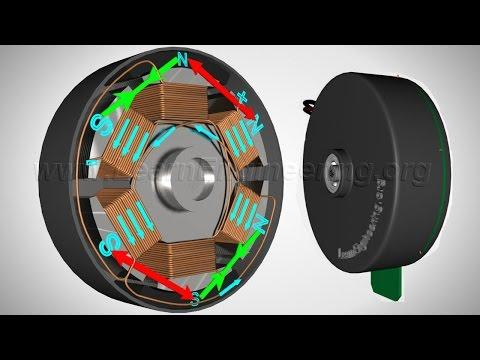

syms timeStep  startTime numSteps timeVector
timeStep=0.01; 
startTime=0;
 numSteps=1000;
 timeVector = timeStep * [startTime:numSteps-1]'; 

 
syms Ra La % armature

La=1 % armature inductance

La = 1

Ra=1 % armature resistance

Ra = 1


syms Fm Im kv kt Mm Rm Ml Rl G Theta Theta_l k % DC motor
Theta=90

Theta = 90

k_gear= 10 % gear reductio ratio

k_gear = 10

G=9.81 % [N] or [m/s^2] % gravity

G = 9.8100

Theta_l= Theta/k_gear % [rad] position

Theta_l = 9

Ml=1 % [Kg] load mass

Ml = 1

Rl=1 % [m] load radius

Rl = 1

Mm=1 % [Kg] motor mass

Mm = 1

Rm=1 % [m] motor radius

Rm = 1

Im = 1/2*Mm*Rm^2 % [Kg*m^2] motor (cilinder) inertia

Im = 0.5000

Fm=1 % [N] or [m/s^2] motor friction 

Fm = 1

kv=1 % torque constant

kv = 1

kt=1 % voltage constant

kt = 1

Tload.time = timeVector;
Tload.signals.values = zeros(size(timeVector));
Tload.signals.dimensions = 1;
 for k=1:length(timeVector)
    Tload.signals.values(k)= 0; % Ml*Rl*G*sin(Theta_l); % [Kg*m^2/s^2] load torque
 end

syms Gv Tv Ki % control

Vc.time = timeVector;
Vc.signals.values = zeros(size(timeVector));
Vc.signals.dimensions = 1;
for k=1:length(timeVector)
    Vc.signals.values(k)=100;
end
Gv=1 % voltage gain constant

Gv = 1

Tv=1 % time constant amplifier

Tv = 1

ki=1 % transducer constant

ki = 1